# Checkbox List

This widget provides an array of checkboxes within a scrollable panel.

Create a figure with a grid layout:

figObj = uifigure("Position",[100 100 250 200]);
gridObj = uigridlayout(figObj,[1 1],"BackgroundColor",[.6 .8 1]);

Create and configure the widget:

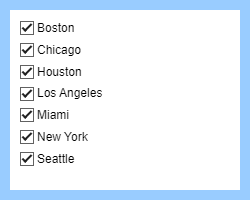

cbListWidget =   CheckboxList with properties:

    ValueChangedFcn: @(src,evt)disp(evt)

              Items: [7×1 string]
              Value: [7×1 logical]
      ShowSelectAll: off
            Tooltip: ""

           Position: [11 11 230 180]
              Units: 'pixels'

  Show all properties


cbListWidget = wt.CheckboxList(gridObj);
cbListWidget.ValueChangedFcn = @(src,evt)disp(evt);

cbListWidget.Items = [
    "Boston"
    "Chicago"
    "Houston"
    "Los Angeles"
    "Miami"
    "New York"
    "Seattle"
    ]

You may toggle values programmatically:

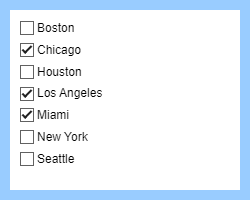

cbListWidget.Value([1 3 6 7]) = false;

Optionally, show a **Select All** option at the top:

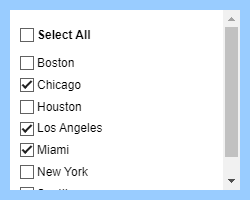

cbListWidget.ShowSelectAll = true;

*Copyright 2020-2025 The MathWorks, Inc.*